# Data preparation

clear; clc; close all;
warning('off');

% If no dataset, download it.
url = 'https://nextcloud.centralesupelec.fr/s/7AR6aamBZNXcRM8/download';
downloadFolder = fullfile('../', 'dataset');
rootDict = fullfile('../');
if ~exist(downloadFolder, 'dir')
    options = weboptions('Timeout', 30);
    loc = websave([downloadFolder '.zip'], url, options);
    unzip(loc, rootDict);
end

% We read the test data.
testDataFolderName = '20241016';
% Load test data
lenSeries = 1000; % Sequence length.
simulationTime = 10; % The time that this sequence corresponds to.
dataLoader = DataLoader(lenSeries, simulationTime);
dataLoader.shuffle = false; % Shuffle the data.

dataLoader.pathLoggedTestData = ['../dataset/testDatasets/' testDataFolderName '/real_testing_dataset.mat'];
dataLoader.pathTestDataset = ['../dataset/testDatasets/' testDataFolderName '/'];
dataLoader.pathOriginalTestData = ['../dataset/testDatasetsOriginal/' testDataFolderName '/'];
dataLoader.nTrajPerLabelTestDataset = 10;
dataLoader.labelList = {'Healthy', ...
    'Motor_1_Stuck', 'Motor_2_Stuck', 'Motor_3_Stuck', 'Motor_4_Stuck', ...
    'Motor_1_Steady_state_error', 'Motor_2_Steady_state_error', 'Motor_3_Steady_state_error', 'Motor_4_Steady_state_error'};
[X, y] = dataLoader.loadTestingData();

Loaded data from ../dataset/testDatasets/20241016/real_testing_dataset.mat


y = categorical(y);

% Create a stratified partition
partition = cvpartition(y, 'HoldOut', 0.2); % 30% for testing

% Get the training and testing indices
trainIdx = training(partition); % Logical array for training set
testIdx = test(partition);      % Logical array for testing set

% Split the data
X_train = X(trainIdx);
y_train = y(trainIdx);
X_test = X(testIdx);
y_test = y(testIdx);

# Original features

Train an LSTM with the orginal features: Commands on motors 1-4, and the measured $x, y, z$ coordiantes of the end-effector. Repeat the experiment $5$ times. 

X_orgFeatures = dataLoader.extractFeaturesOriginal(X_train);
X_test_orgFeatures = dataLoader.extractFeaturesOriginal(X_test);

randSeedInitial = 42;
n_experiment = 5;
epochs = 10:10:50;
n_epochs = length(epochs);

results_tr_org = cell(n_epochs, n_experiment);
results_val_org = cell(n_epochs, n_experiment);
results_test_org = cell(n_epochs, n_experiment);

tic;

miniBatchSize = 5;
trainingRatio = .75;
for k = 1:n_epochs
    maxEpochs = epochs(k);
    fprintf('Maxi Epoch: %d\n', maxEpochs);
    for i = 1:n_experiment
        fprintf('%d/%d\n', i, n_experiment);
    
        randSeed = randSeedInitial+i-1;
        [result_tr, result_val, result_test] = runExperiment(X_orgFeatures, X_test_orgFeatures, y_train, y_test, dataLoader, randSeed, maxEpochs, miniBatchSize, trainingRatio);
        
        results_tr_org{k, i} = result_tr;
        results_val_org{k, i} = result_val;
        results_test_org{k, i} = result_test;
    end
end

Maxi Epoch: 10


1/5
2/5
3/5
4/5
5/5


Maxi Epoch: 20


1/5
2/5
3/5
4/5
5/5


Maxi Epoch: 30


1/5
2/5
3/5
4/5
5/5


Maxi Epoch: 40


1/5
2/5
3/5
4/5
5/5


Maxi Epoch: 50


1/5
2/5
3/5
4/5
5/5


elaspedTimeOrg = toc

elaspedTimeOrg = 340.2388

# Post-processing

First, we compare the performance of using the original features (commands for motors 1-4) and trajctory resposne of the end-effector (x, y z) with that of the augumented features (trajectory response + residuals on x, y, z).

- Training and validation accuracy V.S. terminated epochs

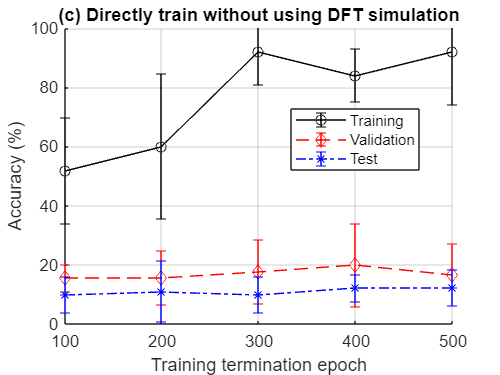

[meanAccTrOrg, stdAccTrOrg] = processTrainingAcc(results_tr_org);
validationFreq = floor(numel(X)*trainingRatio/miniBatchSize);
[meanAccValOrg, stdAccValOrg, indexesValOrg] = processValidationAcc(results_val_org, validationFreq);

[meanAccTestOrg, stdAccTestOrg, otherPerfsOrg] = processTestPerfs(results_test_org);
% Transfer to percentage.
for i = 1:length(meanAccTestOrg)
    meanAccTestOrg{i} = meanAccTestOrg{i}*100;
    stdAccTestOrg{i} = stdAccTestOrg{i}*100;
end

% Define figure size in pixels
width = 400;
height = 300;

figure('Position', [100, 100, width, height]);
plotTrPerfs(meanAccTrOrg, stdAccTrOrg, 'ko-')
plotValPerfs(meanAccValOrg, stdAccValOrg, indexesValOrg, 'rd--')
plotValPerfs(meanAccTestOrg, stdAccTestOrg, indexesValOrg, 'b*-.')
xlabel('Training termination epoch');
ylabel('Accuracy (%)');
title('(c) Directly train without using DFT simulation')
legend('Training', 'Validation', 'Test', 'Location', 'best')
ylim([0, 100])
grid on

2. Print the precision, recall and f1 score for each class: Original features.

trainingAcc = meanAccTrOrg{end}(end);
trainingAccStd = stdAccTrOrg{end}(end);
validationAcc = meanAccValOrg{end}(end);
validationAccStd = stdAccValOrg{end}(end);
testAcc = meanAccTestOrg{end}(end);
testAccStd = stdAccTestOrg{end}(end);

precision = otherPerfsOrg.meanPrecision(end, :);
stdPrecision = otherPerfsOrg.stdPrecision(end, :);
recall = otherPerfsOrg.meanRecall(end, :);
stdRecall = otherPerfsOrg.stdRecall(end, :);
f1Score =  otherPerfsOrg.meanF1(end, :);
stdF1 = otherPerfsOrg.stdF1(end, :);

class_names = categories(y_test);

fprintf('Training Accuracy: %.2f%%+-%.2f%%\n', trainingAcc, trainingAccStd);

Training Accuracy: 92.00%+-17.89%


fprintf('Validation Accuracy: %.2f%%+-%.2f%%\n', validationAcc, validationAccStd);

Validation Accuracy: 16.67%+-10.39%


fprintf('Test Accuracy: %.2f%%+-%.2f%%\n\n', testAcc, testAccStd);

Test Accuracy: 12.22%+-6.09%




for i = 1:numel(class_names)   
    fprintf('Class %d (%s): Precision = %.2f+-%.2f, Recall = %.2f+-%.2f, F1 Score = %.2f+-%.2f\n', ...
        i, class_names{i}, ...
        precision(i), stdPrecision(i),...
        recall(i), stdRecall(i), ...
        f1Score(i), stdF1(i));
end

Class 1 (Healthy): Precision = NaN+-NaN, Recall = 0.10+-0.22, F1 Score = NaN+-NaN
Class 2 (Motor_1_Steady_state_error): Precision = NaN+-NaN, Recall = 0.00+-0.00, F1 Score = NaN+-NaN
Class 3 (Motor_1_Stuck): Precision = NaN+-NaN, Recall = 0.10+-0.22, F1 Score = NaN+-NaN
Class 4 (Motor_2_Steady_state_error): Precision = NaN+-NaN, Recall = 0.00+-0.00, F1 Score = NaN+-NaN
Class 5 (Motor_2_Stuck): Precision = 0.17+-0.24, Recall = 0.20+-0.27, F1 Score = NaN+-NaN
Class 6 (Motor_3_Steady_state_error): Precision = NaN+-NaN, Recall = 0.30+-0.27, F1 Score = NaN+-NaN
Class 7 (Motor_3_Stuck): Precision = NaN+-NaN, Recall = 0.10+-0.22, F1 Score = NaN+-NaN
Class 8 (Motor_4_Steady_state_error): Precision = 0.17+-0.16, Recall = 0.30+-0.27, F1 Score = NaN+-NaN
Class 9 (Motor_4_Stuck): Precision = NaN+-NaN, Recall = 0.00+-0.00, F1 Score = NaN+-NaN


# Supporting scripts

function [results_tr, results_val, results_test] = runExperiment(X, X_test, y, y_test, dataLoader, randSeed, maxEpochs, miniBatchSize, training_ratio)
    rng(randSeed);

    % Shuffle the dataset using the cvpartition function
    n_dataset = numel(X);
    training_size = floor(training_ratio*n_dataset);
    cvObj = cvpartition(y, 'HoldOut', training_size);
    idx = cvObj.test;
    
    % Split into training and test data based on training size specified
    X_train = X(idx');
    X_val = X(~idx');
    y_train = categorical(y(idx'));
    y_val = categorical(y(~idx'));

    interval = 10;
    X_train = dataLoader.downsamling(X_train, interval);
    X_val = dataLoader.downsamling(X_val, interval);
    X_test = dataLoader.downsamling(X_test, interval);

    [X_train, M, S] = dataLoader.standardization(X_train);
    [X_val, ~, ~] = dataLoader.standardization(X_val, M, S);
    [X_test, ~, ~] = dataLoader.standardization(X_test, M, S);

    % Define the network structure.
    % layers = [ ...
    % sequenceInputLayer(size(X_train{1},1))
    % lstmLayer(100,"OutputMode","sequence")
    % dropoutLayer(0.1)
    % lstmLayer(100,"OutputMode","last")
    % fullyConnectedLayer(numel(categories(y_train)))
    % softmaxLayer
    % classificationLayer];

    layers = [ ...
    sequenceInputLayer(size(X_train{1},1))
    lstmLayer(20,"OutputMode","sequence")
    dropoutLayer(0.1)
    lstmLayer(40,"OutputMode","last")
    fullyConnectedLayer(numel(categories(y_train)))
    softmaxLayer
    classificationLayer];

    validationFrequency = floor(numel(X_train)/miniBatchSize);
    options = trainingOptions("adam", ...
        "MaxEpochs", maxEpochs, ...
        "MiniBatchSize",miniBatchSize, ...
        "Verbose",false, ...
        "Shuffle","every-epoch", ...
        "LearnRateSchedule","piecewise", ...
        "LearnRateDropFactor",0.1, ...
        "LearnRateDropPeriod",20,...
        'ValidationData',{X_val, y_val}, ...
        'ValidationFrequency',validationFrequency);

    % Training
    [diagnosisNet, info] = trainNetwork(X_train, y_train, layers, options);

    % Get the training perf.
    results_tr = {info.TrainingAccuracy};

    % Get validation perf.
    % y_pred_val = classify(diagnosisNet, X_val);
    % [accuracy, precision, recall, f1Score] = dataLoader.evalPerf(y_val, y_pred_val);
    % results_val = {accuracy, precision, recall, f1Score};
    results_val = {info.ValidationAccuracy};

    % Get testing perf.
    y_pred = classify(diagnosisNet, X_test);
    [accuracy, precision, recall, f1Score] = dataLoader.evalPerf(y_test, y_pred);
    results_test = {accuracy, precision, recall, f1Score};
end


function [meanAccTr, stdAccTr] = processTrainingAcc(results_tr)
    % For each row (one maxEpoch, get two cell arrays: One is the mean
    % value, and the other is the std of the Acc at each epoch).
    
    [n_rows, n_cols] = size(results_tr);    

    % Process for training accuracy.
    meanAccTr = cell(1, n_rows);
    stdAccTr = cell(1, n_rows);

    for i = 1:n_rows
        seqLength = length(results_tr{i, 1}{1});
        accTrAllCols = zeros(n_cols, seqLength);
        for j = 1:n_cols
            accTrAllCols(j, :) = results_tr{i, j}{1};
        end
        meanAccTr{i} = mean(accTrAllCols);
        stdAccTr{i} = std(accTrAllCols);
    end

end


function [meanAccVal, stdAccVal, indexesVal] = processValidationAcc(results_val, vaildationFreq)
    % For each row (one maxEpoch, get two cell arrays: One is the mean
    % value, and the other is the std of the Acc at each epoch).
    
    [n_rows, n_cols] = size(results_val);    

    % Process for training accuracy.
    meanAccVal = cell(1, n_rows);
    stdAccVal = cell(1, n_rows);
    indexesVal = cell(1, n_rows);    

    for i = 1:n_rows
        curSeq = results_val{i, 1}{1};
        % Find the indexes of non-NaN elements
        idxVal = find(~isnan(curSeq));
        idxVal = idxVal(2:end);
        accTrAllCols = zeros(n_cols, length(idxVal));
        for j = 1:n_cols
            % Extract the non-NaN elements
            curSeq = results_val{i, j}{1};
            nonNanElements = curSeq(idxVal);
            accTrAllCols(j, :) = nonNanElements;
        end
        meanAccVal{i} = mean(accTrAllCols);
        stdAccVal{i} = std(accTrAllCols);
        indexesVal{i} = idxVal;
    end

end


function [meanAccTest, stdAccTest, otherPerfs] = processTestPerfs(results_test)
    % For each row (one maxEpoch, get two cell arrays: One is the mean
    % value, and the other is the std of the Acc at each epoch).
    
    [n_rows, n_cols] = size(results_test);    

    % Process for the accuracy.
    meanAccTest = cell(1, n_rows);
    stdAccTest = cell(1, n_rows);

    n_classes = length(results_test{1, 1}{2});
    meanPrecision = zeros(n_rows, n_classes);
    stdPrecision = zeros(n_rows, n_classes);
    meanRecall = zeros(n_rows, n_classes);
    stdRecall = zeros(n_rows, n_classes);
    meanF1 = zeros(n_rows, n_classes);
    stdF1 = zeros(n_rows, n_classes);


    for i = 1:n_rows
        accTrAllCols = zeros(n_cols, 1);
        precisionAll = zeros(n_cols, n_classes);
        recallAll = zeros(n_cols, n_classes);
        f1All = zeros(n_cols, n_classes);
        
        for j = 1:n_cols
            accTrAllCols(j) = results_test{i, j}{1};
            precisionAll(j, :) = results_test{i, j}{2}';
            recallAll(j, :) = results_test{i, j}{3}';
            f1All(j, :) = results_test{i, j}{4}';
        end
        
        meanAccTest{i} = mean(accTrAllCols);
        stdAccTest{i} = std(accTrAllCols);
        meanPrecision(i, :) = mean(precisionAll);
        stdPrecision(i, :) = std(precisionAll);
        meanRecall(i, :) = mean(recallAll);
        stdRecall(i, :) = std(recallAll);
        meanF1(i, :) = mean(f1All);
        stdF1(i, :) = std(f1All);
    end

    otherPerfs.meanAccTest = meanAccTest;
    otherPerfs.stdAccTest = stdAccTest;
    otherPerfs.meanPrecision = meanPrecision;
    otherPerfs.stdPrecision = stdPrecision;
    otherPerfs.meanRecall = meanRecall;
    otherPerfs.stdRecall = stdRecall;
    otherPerfs.meanF1 = meanF1;
    otherPerfs.stdF1 = stdF1;
end


function plotTrPerfs(meanAcc, stdAcc, format)
    n = length(meanAcc);
    
    terminatedEpochs = zeros(1, n);
    accFinalEpoch = zeros(1, n);
    stdFinalEpoch = zeros(1, n);

    for i = 1:n
        terminatedEpochs(i) = length(meanAcc{i});
        accFinalEpoch(i) = meanAcc{i}(end);
        stdFinalEpoch(i) = stdAcc{i}(end);
    end

    hold on;
    errorbar(terminatedEpochs, accFinalEpoch, stdFinalEpoch, format);
end


function plotValPerfs(meanAcc, stdAcc, indexesVal, format)
    n = length(meanAcc);
    
    terminatedEpochs = zeros(1, n);
    accFinalEpoch = zeros(1, n);
    stdFinalEpoch = zeros(1, n);

    for i = 1:n
        terminatedEpochs(i) = indexesVal{i}(end);
        accFinalEpoch(i) = meanAcc{i}(end);
        stdFinalEpoch(i) = stdAcc{i}(end);
    end

    hold on;
    errorbar(terminatedEpochs, accFinalEpoch, stdFinalEpoch, format);
end